## 1D field visualization

TODO

- add GAUSS, LINEAR

- interp not working

- lower the grid resolution

generate map

grid = OctoGrid(2,2,2,100);

% add wall
grid.addBox(0.6,0.8,0,0.8,0.1,1.5)

generate phase

y = 0.4:0.01:1.3

y =     0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900    0.5000    0.5100    0.5200    0.5300    0.5400    0.5500    0.5600    0.5700    0.5800    0.5900    0.6000    0.6100    0.6200    0.6300    0.6400    0.6500    0.6600    0.6700    0.6800    0.6900    0.7000    0.7100    0.7200    0.7300    0.7400    0.7500    0.7600    0.7700    0.7800    0.7900    0.8000    0.8100    0.8200    0.8300    0.8400    0.8500    0.8600    0.8700    0.8800    0.8900


sample map

map_list = [];

x = 1;
z = 1;

% list of obstacle values
map_list = [map_list grid.grid(ceil(y*grid.resolution), x*grid.resolution, z*grid.resolution)];

draw map plot

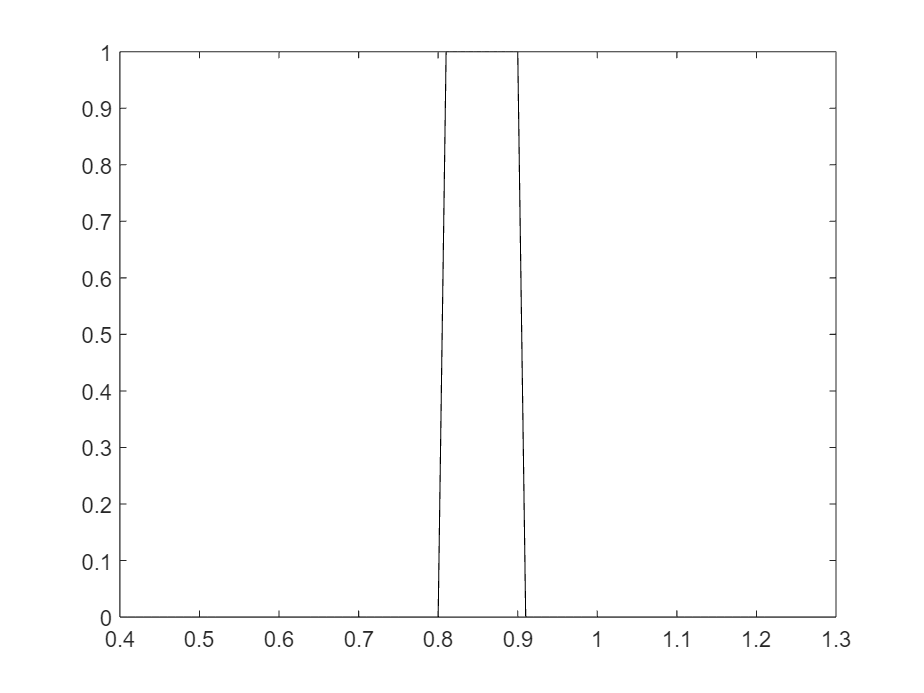

figure()

plot(y, map_list,'black')
hold on

generate kernels

rep_kernels = REP_kernels();

draw grid on plot the size of resolution

generate LINEAR, GAUSS, LINEAR+INTERP, GAUSS+INTERP samples

rep_values = [];
tic()
for i = y
    rep_values = [rep_values REP_field_calculation(grid, rep_kernels, [x,i,z])'];
end
toc()

Elapsed time is 0.026811 seconds.


plot samples

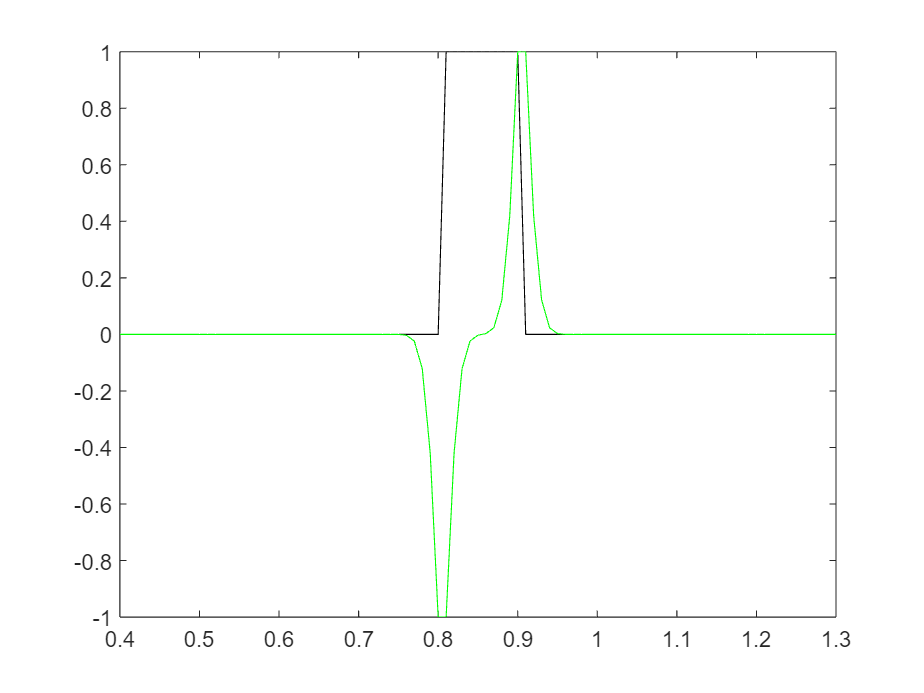

plot(y, (rep_values(2,:))/max(rep_values(2,:)),'green')
hold on

add legend